# 10/30

%look at velocities; are most responsive cells central to domains? 
%load and format tracks 
cd C:\Users\Hailey\CPSAM_OriginalUTURN
filename='CPSAM_Original_Tracks.xml'; %'pos1croptest_Tracks.xml';%; %'pos1croptest_Tracks.xml' %'Pos1_Tracks.xml'; %7.23.25 pos 1 dataset
labelstif='C:\Users\Hailey\CPSAM_OriginalUTURN\LabelImageSeq\LblImgALL.tif'; %'LblImg_pos1croptestlabels.tif' %'LblImg_pos1_labels.tif';
directory='C:\Users\Hailey\CPSAM_OriginalUTURN\LabelImageSeq\';

[tracks, disps]=TracksForm(filename,labelstif,mindur=60,stimstart=1);
 
%re-modify tracks
msdtracks=tracks;
for i=1:length(tracks)
    msdtracks{i}=tracks{i}(:,1:3);
end
% Initialize the MSD analyzer with the specified parameters
ma = msdanalyzer(2, 'px', 'frame');
ma = ma.addAll(msdtracks);
v = ma.getVelocities;
ma = ma.computeVCorr;

Computing velocity autocorrelation of 391 tracks... Done.


%add column for velocity magnitude in column 4
for i=1:length(v)
    for j=1:length(v{i})
    v{i}(j,4)=sqrt(v{i}(j,2)^2+v{i}(j,3)^2);
    end
end

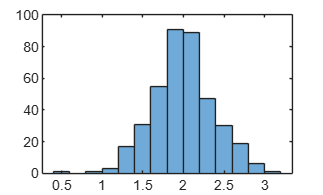

%velocities range from 0 to about 6 (w high exceptions...)
% want to look at mean x speeds (whole track, pre-turn...) and where the
% fastest are.

%pre-turn mean speeds taking frames 1-30
meanSpeeds = zeros(length(tracks), 1);
for i=1:length(tracks)
    [~,I]=find(v{i}(:,1)<30);
    preturn=length(I);

    meanSpeeds(i)= mean(abs(v{i}(12:preturn+1,2)));
    %meanSpeeds(i)= mean(v{i}(:,4));
    %meanSpeeds(i)= mean(v{i}(preturn:preturn+5,4));
end

[leaderspeed,leader]=sort(meanSpeeds,'descend');
figure
histogram(leaderspeed)

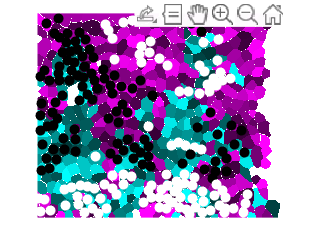

%lets look at cells with mean pre-turn speed over 4. rows 1-46
figure
%im=imread("C:\Users\Hailey\CPSAM_OriginalUTURN\1.50 s.tif");
im=imread("C:\Users\Hailey\CPSAM_OriginalUTURN\UD_CYAN-MAGENTA\Original_0029.tif");
imshow(im)
hold on
for i=1:100%length(tracks)
    %find(tracks{leader(i)}(:,1)==30);
    scatter(tracks{leader(end-i)}(30,2),tracks{leader(end-i)}(30,3),'w','filled');
    scatter(tracks{leader(i)}(30,2),tracks{leader(i)}(30,3),'k','filled');

end

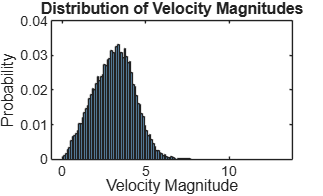

% Analyze the distribution of velocity magnitudes
velocityMagnitudes = cellfun(@(x) x(:,4), v, 'UniformOutput', false);
allVelocities = vertcat(velocityMagnitudes{:});
figure;
histogram(allVelocities, 'Normalization', 'probability');
xlabel('Velocity Magnitude');
ylabel('Probability');
title('Distribution of Velocity Magnitudes');

# 10/3

load('7.23.25_Pos1_WORKINGSET.mat',"disps","downs","ups","pivots","tracks");
tic
[pivots,xmins]=Pivots(tracks,disps,'distance',5);
toc

Elapsed time is 0.100960 seconds.


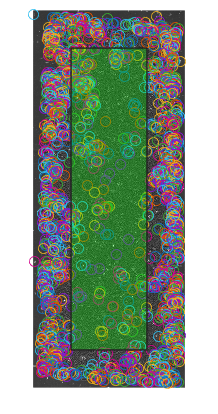


% take a look at spatial distribution of tracks that do not turn/
%reach xmin before stimswitch
figure
earlies=find(xmins<33);
im=imread("E:\CohenLab\7.23.25_CORGI_UTURN\Pos1\pos1_ROTTempMCROP8bit\pos1_09.tif");
imshow(im)
hold on
for i=earlies
    scatter(tracks{i,1}(1,2),tracks{i,1}(1,3))
    
end
%looks like they are almost all edge cells, which I probably want
%to exclude from this analysis for now anyway.

%plot a scaled down rectangle to check bulk cropping bounds:
prop1=0.5;
prop2=0.2;
x1=(size(im,2)*prop1)/2;
x2=size(im,2)-x1;
y1=(size(im,1)*prop2)/2;
y2=size(im,1)-y1;
x=[x1 x1 x2 x2];
y=[y2 y1 y1  y2];
patch(x,y,'green','FaceAlpha',0.3)

hold off; % Release the plot hold

%crop data to the bulk
BulkTracks={};
BulkDisps={};
BulkUps=[];
BulkDowns=[];
prop1=0.5;
prop2=0.2;
x1=(size(im,2)*prop1)/2;   x2=size(im,2)-x1;
y1=(size(im,1)*prop2)/2;  y2=size(im,1)-y1;
for i=1:length(tracks)
    if tracks{i,1}(1,2:3)<[x2 y2] & tracks{i,1}(1,2:3)>[x1 y1]
        BulkTracks{end+1,1}=tracks{i}; % Store the current track in BulkTracks
        BulkDisps{end+1,1}=disps{i};
        if ismember(i,ups)
            BulkUps(end+1)=i;
        elseif ismember(i,downs)
            BulkDowns(end+1)=i;
        end
    end
end

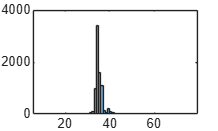

%check if cropping reduces the amount of early xmin cells
[pivots,xmins]=Pivots(BulkTracks,BulkDisps,'distance',5);
figure 
histogram(xmins)


test=length(find(xmins<33));
test/length(BulkDisps)

ans = 0.0323

%about 3.23% of cells still turn early (264). Probably ok.


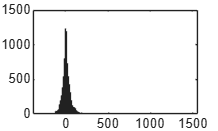

%OK now I want to look at the distribution of AUCs. How many turns are wide
%vs pretty narrow?

%alter UDclasser to output AUC lists in order of track index (not label ID)

[ups,downs,dcurve]=UDclasser(pivots,1:length(pivots),0);

figure
histogram(dcurve)

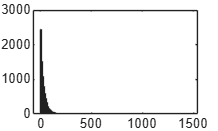

figure
histogram(abs(dcurve))

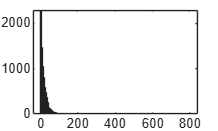

%scale dcurve to microns
dcurve=dcurve*0.7364^2;
figure
histogram(abs(dcurve))

%sort by largest to smallest MAGNITUDE to take a look...
[dclist,list]=sort(abs(dcurve));



%where are the widest turns?

figure
widest=list(1:1000);
im=imread("E:\CohenLab\7.23.25_CORGI_UTURN\Pos1\pos1_ROTTempMCROP8bit\pos1_09.tif");
imshow(im)
hold on
for i=widest'
    scatter(BulkTracks{i,1}(1,2),BulkTracks{i,1}(1,3),'r')
    
end


%figure
narrowest=list(end-1000:end);

narrowest =         3816        8009        7320        7595        6965        6813        5525        7802        1267        8029        4152         492        2399        7041        1694        3060          88        7685        1946        5673        4831         810        4864        2528        6258        6724        2343        4175        7370        3312        4817        5897        4553        2233        6257        6560        3534        2892        4009        6634        7584        5909        2135        5458        8005        7258          44         754        4132        5461


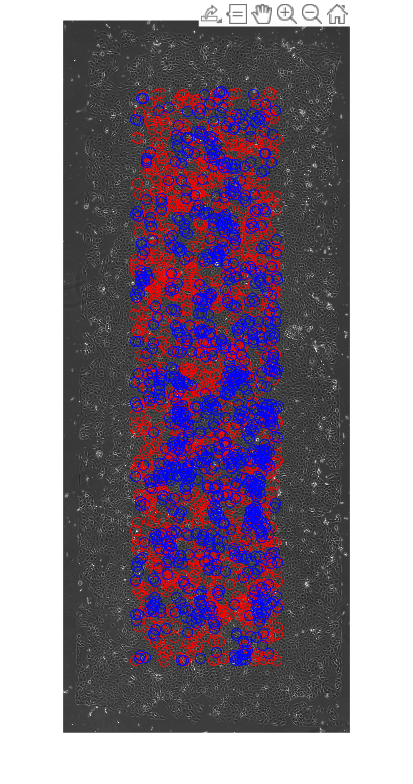

%im=imread("E:\CohenLab\7.23.25_CORGI_UTURN\Pos1\pos1_ROTTempMCROP8bit\pos1_09.tif");
%imshow(im)
hold on
for i=narrowest
    scatter(BulkTracks{i,1}(1,2),BulkTracks{i,1}(1,3),'b')
    
end


%seems like there is some clustering here. How does it compare to u/d
%clustering?

fig =   Figure (14) with properties:

      Number: 14
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [383 189 560 337.2662]
       Units: 'pixels'

  Show all properties


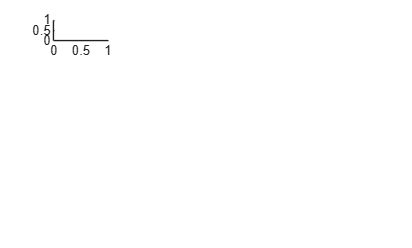

Error using surf (line 71)
Data dimensions must agree.

Error in TilePlot (line 50)
        surf([x(:) x(:)], [y(:) y(:)], [z(:) z(:)], ...  % Reshape and replicate data
        ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

%I want to have a look at some of the "widest" and "narrowest" turns to see
%how this dcurve metric is doing intuitively
%TilePlot('N',0,list(end-24:end),tracks,disps);